clc;
clear;
close all;

## 添加路径

addpath('plane wave\')
addpath('镜头\')

## 参数设置

# Gaussian Beam

lambda=647e-6;
beamSize=2;       %初始高斯光束腰斑直径
beamStd=beamSize/2.85;
beamAmp=1;
noise=0.5;
beam=GaussianBeam(beamAmp,beamStd,lambda);
color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, 'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
colormap(mymap)

# MLA

rla1=-1.1;% 透镜1的曲率半径    
d = 0.15;% 透镜单元边长
t = 1.2;% 透镜厚度
N=40;% 微透镜单元采样点数
material={"F_SILICA"};
MLA1=Lens([rla1,inf],t,d,material,lambda);

MLA2=Lens([inf,-rla1],t,d,material,lambda);

num=floor(beamStd/d*5);            %数量
if num==0
    num=1;
end
area1 = num*d;           % 光场的面积
area2=12.8;
area3=12.8;
rate=(d/N);           %采样率（global）
area2=findClosestDivisible(area2,rate);

peak=0;
SD=0;
uniformity=0;
beams=GaussianBeam.defocused(beam,10,N*num,rate);%.*drawCircle(round(N*num)/2,0,0,round(area1/rate),round(area1/rate));
beamApt=drawCircle(round(size(beams,1)/2),0,0,size(beams,1),size(beams,2));
beams=beams.*beamApt;
I_sum=sum(abs(beams).^2,'all');

# Ex-MLA

rla_ex = -1.6;            % 透镜1的曲率半径
d_ex = 0.15;              % 透镜单元边长
t_ex=1;
material_ex={"F_SILICA"};
MLA3=Lens([rla_ex inf],t_ex,d_ex,material_ex,lambda);


aperture=drawCircle(23/2/rate,0,0,round(area3/rate),round(area3/rate));

distance1 = 1;   % 投影距离
distance2 = 70;   % 投影距离
distance3 = 74.9;
distance4 = 2.795;

# Fourier Lens

%{
rfl1 = -386.511;            % 傅里叶透镜的曲率半径（胶合透镜）
rfl2 = -132.37;
rfl3 = 185.841;
dfl = 40;              % 傅里叶透镜直径
tfl = [3,5];            % 傅里叶透镜厚度
material_fl={'ZF2','H-K9L'};
FL=Lens([rfl1,rfl2,rfl3],tfl,dfl,material_fl,lambda);
%}
Dfl = area2;              %采样区域
%file='Lens.txt';
%file='OLD2444-T2M(JCOPTIX-F=100胶合).txt';
file='OLD2440-T2M(JCOPTIX-F=74.9胶合).txt';
%file='OLD2430-T2M(JCOPTIX-F=30胶合).txt';
%{
f_str=strsplit(file,'F=');
ff_str=strsplit(f_str{2},'胶合');
f_FL=ff_str{1};
%}
FL=readLens(file,lambda);

# Telescope

mag=1;
focallen1=75*mag;
focallen2=75;

Tele2=Lens(focallen2);

# Diffuser

rpm=50000;%电机转速(圈每分钟)
rpus=rpm/60/1000/1000;
radius_diffuser=22;%散射片半径mm
velocity=2*pi*rpus*radius_diffuser;%线速度
deltat=N*num*0.033*rate/velocity;%
T=50;%积分时间（μs）
times=floor(T/deltat);
route=velocity*T;
if route>2*pi*radius_diffuser
    route=2*pi*radius_diffuser;
    T=route/velocity;
    times=floor(T/deltat);
end
diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);
phase=Diffuser.generateDiffuser(diffuser,rate,[round(route/rate)+size(beams,1),N*num]);

## 生成透镜相位

%%生成望远镜厚度函数

Lens.lensPhase_paraxial(Tele2,area1,rate,lambda);
%%生成匀光微透镜阵列厚度函数
Lens.lensArrayThickFcn(MLA1,N,num,'square');
Lens.lensArrayThickFcn(MLA2,N,num,'square');
%% 生成傅里叶透镜厚度函数
Lens.lensThickFcn(FL,Dfl,round(area2/rate));
%% 生成激发微透镜阵列厚度函数
lensArray.lensArrayThickFcn2(MLA3,d_ex/rate,area3/d_ex,'square',0,d_ex-0.001,0)


Lens.lensSingle(Tele2)
Lens.lensSingle(MLA1)
Lens.lensSingle(MLA2)
Lens.lensSingle(FL);

beams=single(beams);
N=single(N);
num= single(num);
Diffuser.diffuserSingle(diffuser)
rate= single(rate);
lambda= single(lambda);
distance2= single(distance2);
distance3= single(distance3);
distance4= single(distance4);
area1= single(area1);
area2= single(area2);
area3= single(area3);

if canUseGPU
    Lens.lensGPUArray(Tele2)
    Lens.lensGPUArray(MLA1)
    Lens.lensGPUArray(MLA2)
    Lens.lensGPUArray(FL)
    beams=gpuArray(beams);
    N= gpuArray(N);
    num= gpuArray(num);
    Diffuser.diffuserGPUArray(diffuser)
    rate= gpuArray(rate);
    lambda= gpuArray(lambda);
    distance2= gpuArray(distance2);
    distance3= gpuArray(distance3);
    distance4= gpuArray(distance4);
    area1= gpuArray(area1);
    area2= gpuArray(area2);
    area3= gpuArray(area3);
end

lensgroup={Tele2,MLA1,MLA2,FL};
area=[area1,area1,area1,area2,area3];
pp=75;
u=zeros(length(mag),pp);
sigma=u;
for kk=1:length(mag)
    Tele1=Lens(focallen1(kk));
    Lens.lensPhase_paraxial(Tele1,area1,rate,lambda);
    Lens.lensSingle(Tele1)
    if canUseGPU
        Lens.lensGPUArray(Tele1)
    end
    distance_tele1=linspace(0,(focallen2+focallen1(kk)),pp);
    distance_tele2=focallen2+focallen1(kk)-distance_tele1;
for jj=1:length(distance_tele1)
    I=zeros(round(area3/rate));
    distance=[distance_tele2(jj),50,distance1,distance2,distance3];

## 光场变换

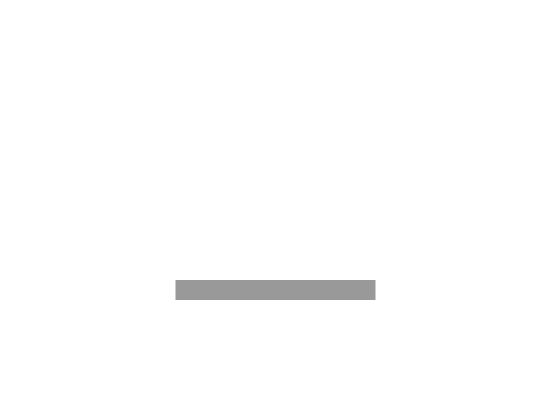

    for ii=1:times
        %叠加随机相位
        beamss=GaussianBeam.beamNoise(beams,0.3,0);
    
        F = transform(beamss, area1, lambda, 20, [rate, rate]);
        afterLens=F.*Tele1.phase;
        F = transform(afterLens, area1, lambda, distance_tele1(jj), [rate, rate]);
        index=round((velocity*(ii-1)*deltat)/rate+1);
        F=F.*phase(index:index+size(F,1)-1,:);
    
        F=ASMlensgroup(F,lensgroup,distance,area,lambda,rate);
    
    
        I_now=abs(F).^2;
        I = I+I_now;
    
        
        subplot(12,10,[91,100])
        progressBar([100,1000],ii/times)
        drawnow
    end

    Inorm=imnorm(I);   
    subplot(12,10,[1,90])       
    imshow(uint16(Inorm*65536),mymap)
    if jj==1
        threshold=otsuthresh(imhist(Inorm));
        im2=Inorm>threshold;
    end

函数或变量 'Inorm' 无法识别。

   
    [u(kk,jj),sigma(kk,jj)]=homoanalyse3(Inorm,im2);
    subplot(12,10,[101,110])
    progressBar([100,1000],jj/length(distance_tele1))  
end
    subplot(12,10,[111,120])
    progressBar([100,1000],kk/length(pp))
end

figure
lensgroup={MLA1,MLA2,FL};
area=[area1,area1,area2,area3];
I=zeros(round(area3/rate));
distance=[50,distance1,distance2,distance3];
for ii=1:times
    %叠加随机相位
    beamss=GaussianBeam.beamNoise(beams,0.3,0);
    F = transform(beamss, area1, lambda, 20, [rate, rate]);
    index=round((velocity*(ii-1)*deltat)/rate+1);
    F=F.*phase(index:index+size(F,1)-1,:);

    F=ASMlensgroup(F,lensgroup,distance,area,lambda,rate);


    I_now=abs(F).^2;
    I = I+I_now;

    Inorm=imnorm(I);
    
    subplot(11,10,[1,90])       
    imshow(uint16(Inorm*65536),mymap)
    Inorm=gather(Inorm); 
    subplot(11,10,[91,100])
    progressBar([100,1000],ii/times)
    drawnow
end
[u0,sigma0]=homoanalyse3(Inorm,im2);

figure
color1=[0.0745    0.6000    0.6980];
color2=[0.9922    0.4627    0.2471];
colororder([color1;color2])
yyaxis left
plot(distance_tele1,u,'color',color1,'linewidth',1.5)
hold on
plot([0,150],[u0,u0],'linewidth',1.5)
xlabel('Position of the diffuser/mm')
ylabel('{\it{u}}')
yyaxis right
plot(distance_tele1,sigma,'color',color2,'linewidth',1.5)
hold on
plot([0,150],[sigma0,sigma0],'linewidth',1.5)
ylabel('\sigma(%)')
set(gca,'Fontname','Times New Roman','fontsize',15,'linewidth',2)
grid on
pos=get(gca,'position');
%set(gca,'position',[pos(1),pos(2)-0.005,pos(3),0.6])
legend('\itu\rm with telescope','\itu\rm without telescope','\it\sigma\rm with telescope','\it\sigma\rm without telescope','location','NorthOutside')
